# **基于亮点模型的潜艇回波仿真**

***参考文献:***

***基于亮点模型的潜艇回波仿真  何心怡 蒋兴舟 林建域***

***一种基于亮点模型的潜艇回波仿真  董仲臣 ,李亚安,陈 晓***

clc;clear;close all;

## 1.仿真发射信号

信号的包络是一个梯形

信号的参数

%入射角
theta = 0;
% 定义时间参数
fs = 20e3;
t = 0:1/fs:1.5 - 1/fs; % 时间向量，这里生成0到0.14秒的时间序列，采样间隔为1/fs
Ts = 1/fs;
fc = 5e3;
c = 1500;
% 定义梯形脉冲参数
Am = 1; % 幅度为1V
%总脉宽120ms，上升10ms，下降10ms
width = 100e-3; % 宽度为100ms
rise_time = 10e-3; % 上升时间设为10ms
fall_time = 10e-3; % 下降时间设为10ms

生成包络

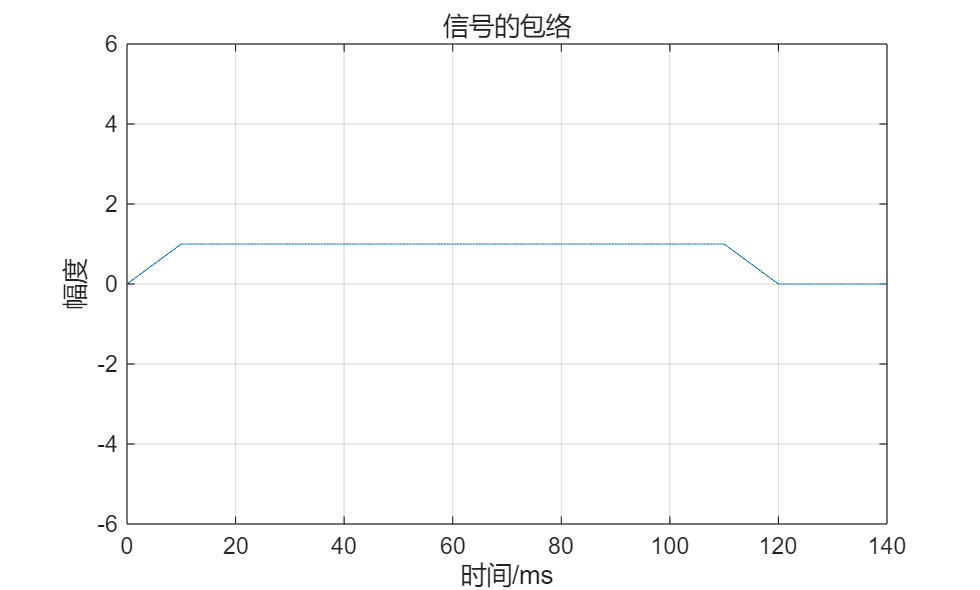


 a = zeros(size(t));
% for i = 1:length(t)
%     if t(i) >= 0 && t(i)<width
%         a(i)  = Am;
%     else
%         a(i) = 0;
%     end
% end
% figure;
% plot(t*1e3, a);
% xlabel('时间/ms');ylabel('幅度');title('信号的包络');
% grid on;
% axis([0,140,-6,6]);

%生成梯形脉冲
for i = 1:length(t)
    if t(i) >= 0 && t(i) < rise_time
        a(i) = Am * t(i) / rise_time;
    elseif t(i) >= rise_time && t(i) < rise_time + width
        a(i) = Am;
    elseif t(i) >= rise_time + width && t(i) < rise_time + width + fall_time
        a(i) = Am - Am * (t(i) - (rise_time + width))/fall_time;
    end
end
%绘制梯形脉冲信号
figure;
plot(t*1e3, a);
xlabel('时间/ms');ylabel('幅度');title('信号的包络');
grid on;
axis([0,140,-6,6]);

发射的窄带脉冲

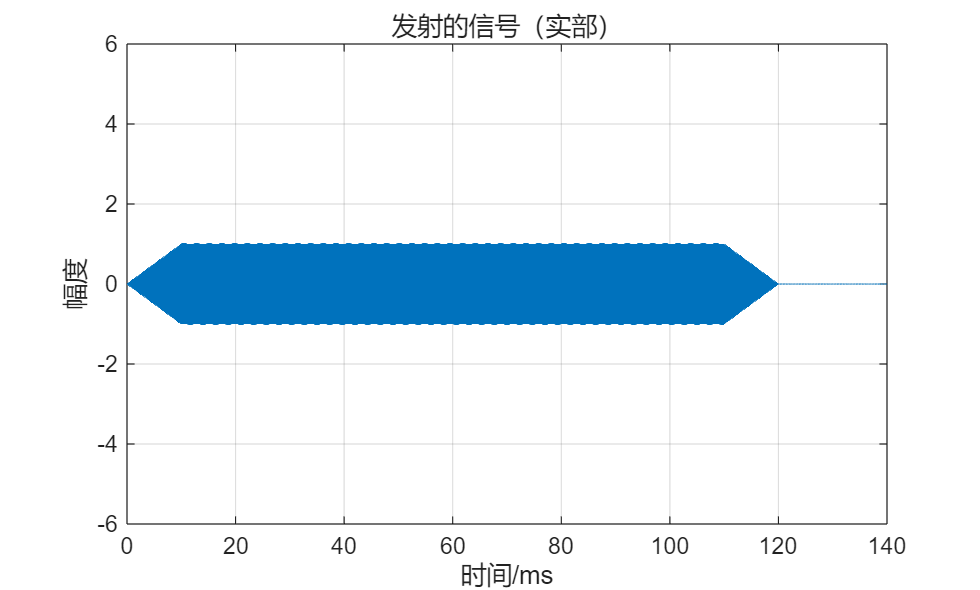

wc = 2*pi*fc;
P = a.*exp(j*wc*t);
figure;
plot(t*1e3, real(P));
xlabel('时间/ms');ylabel('幅度');title('发射的信号（实部）');
grid on;
axis([0,140,-6,6]);

## 2.多普勒频移

潜艇运动产生的多普勒频移：

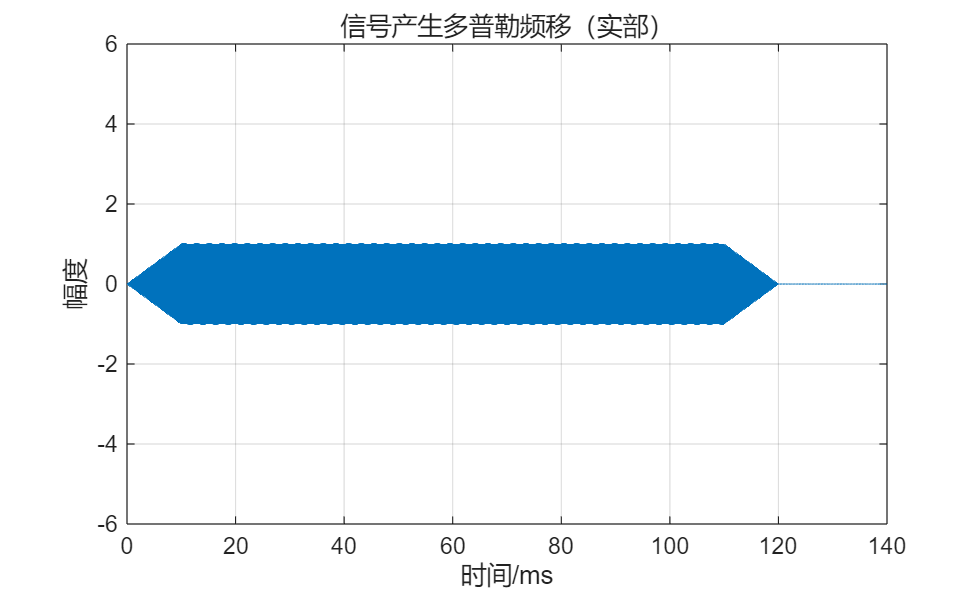

v = 4.112;%潜艇运动速度8海里/h      0.514*8
wd = 2*wc*v*cos(theta*pi/180)/c;%多普勒角频率

PWithDoplar = P.*exp(1j*wd*t);
figure;
plot(t*1e3, real(P));
xlabel('时间/ms');ylabel('幅度');title('信号产生多普勒频移（实部）');
grid on;
axis([0,140,-6,6]);

## 使用Bellhop计算脉冲响应

发射的信号经过信道，此时要经过bellhop生成冲激响应

figure;
plotssp('Env\shallowEnv');

不支持将脚本 plotssp 作为函数执行:
D:\06_packages\AcTUP v2.2L\AT\Matlab\plotssp.m

title('声速梯度');

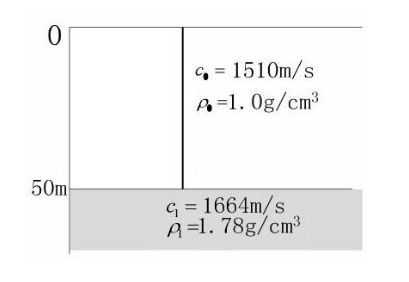

bellhop('Env\shallowEnv');
figure;plotray( 'Env\shallowEnv' ); % 绘制声线轨迹

bellhop( 'Env\shallowEnv' ) % 计算声场并检查输入文件
figure;plotray( 'Env\shallowEnv' ); % 绘制本征声线


% load('impulse.mat');%变量Amp_Delay的第一列是时延，第二列是幅度
% discDelay = round(Amp_Delay(:,1)./(1/fs));
% IR = zeros(1,length(t));
% 
% for i = 1:length(discDelay)
%     IR(discDelay(i)) = abs(Amp_Delay(i,2));
% end
% figure;
% plot(t,IR);xlabel('时间/s');ylabel('归一化幅度');grid on;
% title('信道冲激响应');
% P1 = conv(IR,P,'same');
% figure;
% subplot(2,1,1);
% plot(t, real(P));
% xlabel('时间/s');ylabel('幅度');title('发射的信号（实部）');
% grid on;
% axis([0,0.14,-6,6]);
% subplot(2,1,2);
% plot(t, real(P1));
% xlabel('时间/s');ylabel('幅度');title('经过信道的信号（实部）');
% grid on;
% axis([0,1.5,-1e-4,1e-4]);

## 3.每个亮点的时延

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

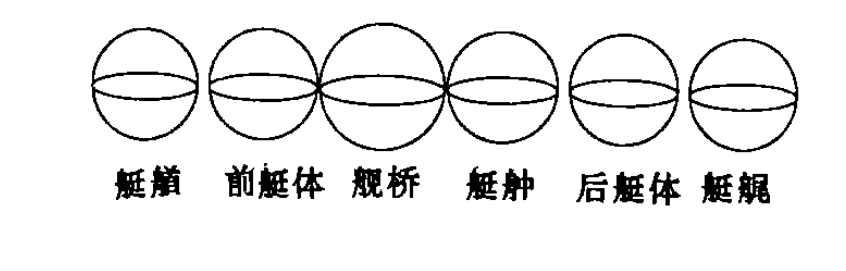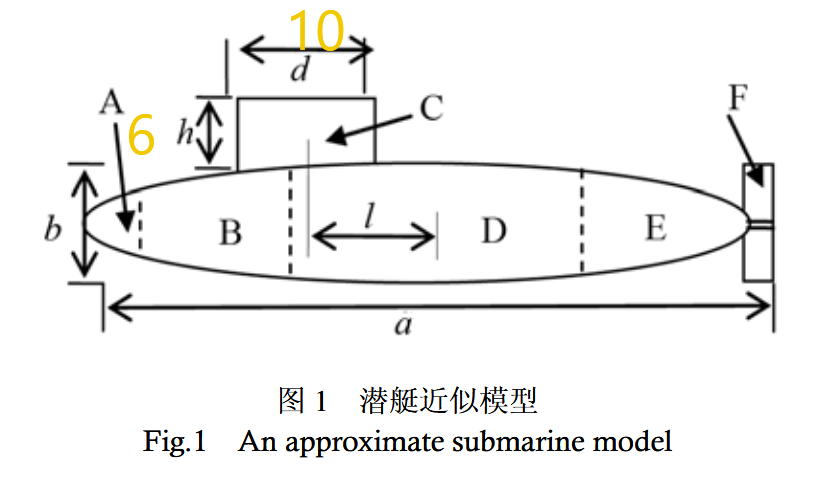

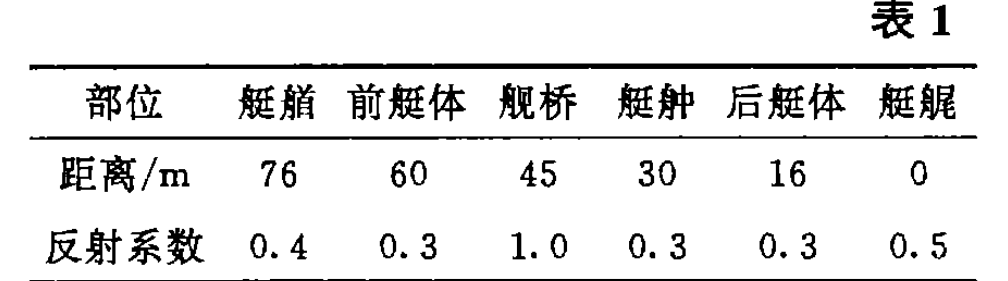

tau = zeros(6,1);
L = zeros(6,1);  %L存放亮点与艇艇的距离
L = [76,   60,     45,   30,   16,   0]; 
R = 5000;    %两者的距离5km
c = 1541.5;    %声速1541.5m/s

 for j = 1:6
      term1 = (R + L(j)*cos(theta*pi/180)).^2;
      term2 = (L(j)*sin(theta))^2;
      numerator = 2*sqrt(term1 + term2);
      tau(j) = numerator/c;
 end


## 4.计算亮点的子回波幅度

计算每个亮点的半径（这里数据不全）

% 定义距离和反射系数
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];
r = [7,7,8,7,7,7];

### 计算隐蔽系数

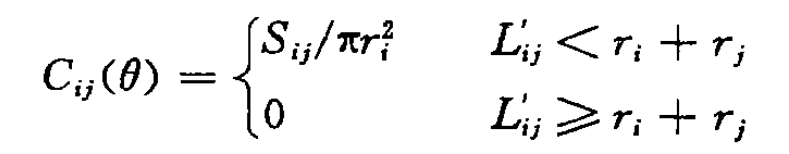

计算Sij

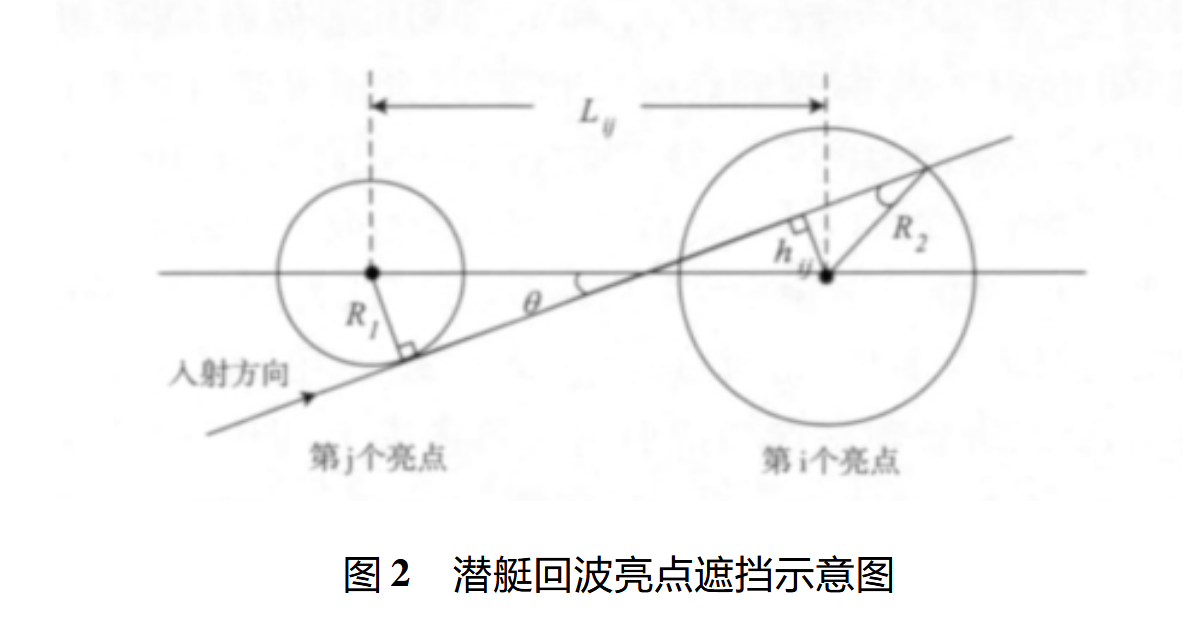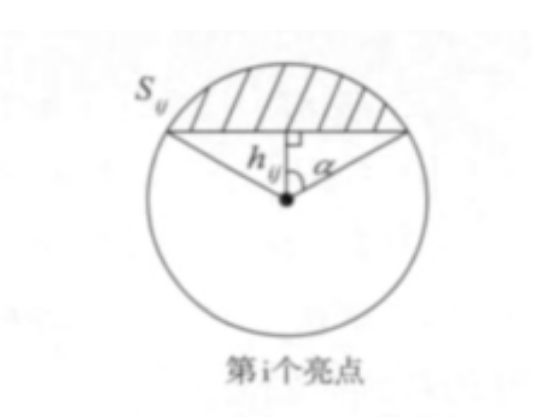

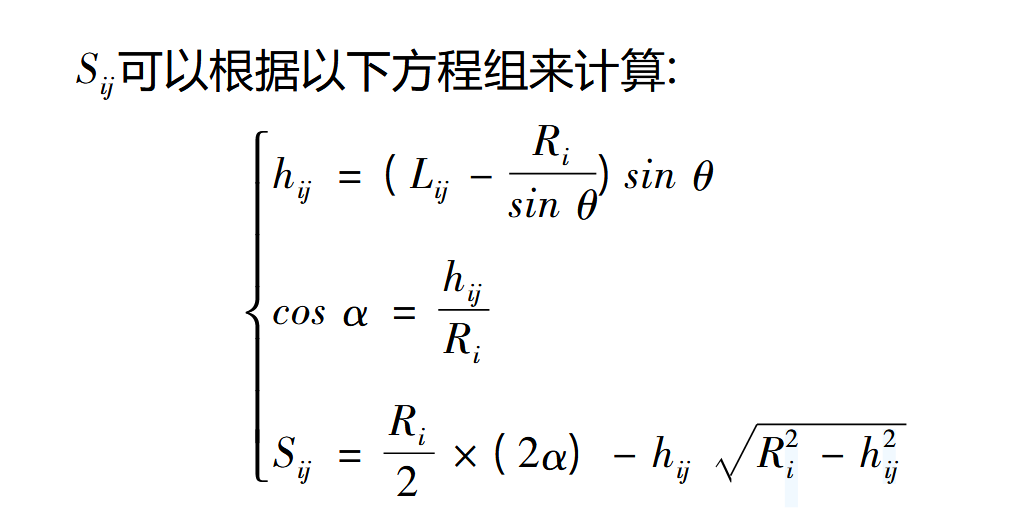

L_ij = zeros(6,6);
h_ij = zeros(6,6);
S_ij = zeros(6,6);

for i =1:6
    for j = 1:6
        L_ij(i,j) =abs( L(j) - L(i) );
        h_ij(i,j) = (L_ij(i,j) - r(i)/(sin(theta*pi/180)+eps) ).*sin(theta*pi/180);
        alpha = acos(h_ij(i,j)/r(i));
        S_ij(i,j) = r(i).^2 /2.*(2*alpha) - h_ij(i,j)*sqrt(r(i).^2 - h_ij(i,j).^2);

      %  C_ij(i,j) = S_ij(i,j)./(pi*r(i).^2);
    end
end


任何一个亮点最多可能被5个亮点所遮挡，最多也就有5个隐蔽系数,那么亮点i的隐蔽系数等于其中最大的隐蔽系数:

一个亮点的实际反射系数为

则一个亮点在考虑有隐蔽情况下其目标强度为

该亮点子回波的幅度为

% 计算隐蔽系数
C_ij = zeros(6,6);
for i = 1:6
    for j = 1:6
        if ( L_ij(i,j)*cos(theta*pi/180) ) < r(i) + r(j)   %传播方向上的投影长度小于亮点半径之和
            C_ij(i, j) = S_ij(i,j)/(pi  *  (r(i).^2)  ); % 由于没有S_ij数据，这里设为0
        else
            C_ij(i, j) = 0;
        end
    end
end

% 计算每个亮点的实际反射系数
B = zeros(1, 6);
for i = 1:6
    C(i) = max(C_ij(i, :));
    B(i) = b(i) .* (1 - C(i));
    % 计算目标强度
    TS(i) = 10 * log10(r(i).^2 / 4) + 10 * log10(B(i));
    
    % 计算亮点子回波幅度
    A(i) = 10.^(TS(i) / 20);
end

% 输出结果
disp(A);

## 5.计算相位

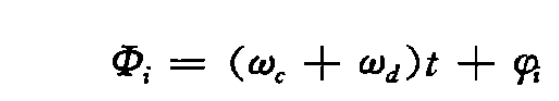

phi = pi;%假设相位跳变180°
Phi = (wc + wd).*t + phi;

## 6.计算回波

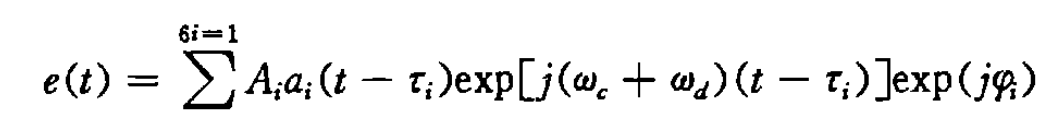

给包络加入时延：

disp(tau);
discDelay = round(tau./Ts);
disp(discDelay);

t = 0:1/fs:10 - 1/fs; % 时间向量，这里生成0到2秒的时间序列，采样间隔为1/fs
dotNum = length(a);
dotNumNew = length(t);

aWithDelay = zeros(6,length(t));
for i =1:6
    aWithDelay(i,:) = [zeros(1,discDelay(i)), a , zeros(1,dotNumNew-discDelay(i)-dotNum)];
end
figure
plot(t, real(aWithDelay(1,:)));
xlabel('时间/s');ylabel('幅度');title('艇艏回波包络');
grid on;
axis([0,10,-3,3]); 

载波加入时延：


PWithDoplarAndDelay = zeros(6,length(t));
for i =1:6
    PWithDoplarAndDelay(i,:) = [zeros(1,discDelay(i)), PWithDoplar , zeros(1,dotNumNew-discDelay(i)-dotNum)];
end
figure
plot(t, real(PWithDoplarAndDelay(1,:)));
xlabel('时间/s');ylabel('幅度');title('艇艏回波');
grid on;
axis([0,10,-3,3]); 

e = zeros(6,dotNumNew);
for i = 1:6
    e(i,:) = A(i).*aWithDelay(i,:).*PWithDoplarAndDelay(i,:).*exp(1j*phi);
end
figure
plot(t, abs(e(1,:)));
xlabel('时间/s');ylabel('幅度');title('艇艏回波包络');
grid on;
axis([0,10,-3,3]); 

各个部位亮点的回波：

figure;
%艇艏亮点的回波：
subplot(3,2,1)
plot(t, real(e(1,:)));
xlabel('时间/s');ylabel('幅度');title('艇艏');
grid on;
axis([6,7,-3,3]);  
%前艇体
subplot(3,2,2)
plot(t, real(e(2,:)));
xlabel('时间/s');ylabel('幅度');title('前艇体');
grid on;
axis([6,7,-3,3]);  
%舰桥
subplot(3,2,3)
plot(t, real(e(3,:)));
xlabel('时间/s');ylabel('幅度');title('舰桥');
grid on;
axis([6,7,-3,3]); 
% 艇舯 
subplot(3,2,4)
plot(t, real(e(4,:)));
xlabel('时间/s');ylabel('幅度');title('艇舯');
grid on
axis([6,7,-3,3]);  
% 后艇体
subplot(3,2,5)
plot(t, real(e(5,:)));
xlabel('时间/s');ylabel('幅度');title('后艇体');
grid on;
axis([6,7,-3,3]);  
% 艇艉
subplot(3,2,6)
plot(t, real(e(6,:)));
xlabel('时间/s');ylabel('幅度');title('艇艉');
grid on;
axis([6,7,-3,3]);  
sgtitle(sprintf('入射方位角%.1f°时各个部位回波(实部)', theta));

disp(r);

整个舰体的回波

echo = sum(e,1);
figure;
%回波：
plot(t, real(echo));
xlabel('时间/s');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波(实部)', theta));
grid on;
axis([6.5,7,-6,6]);

论文中的结果：

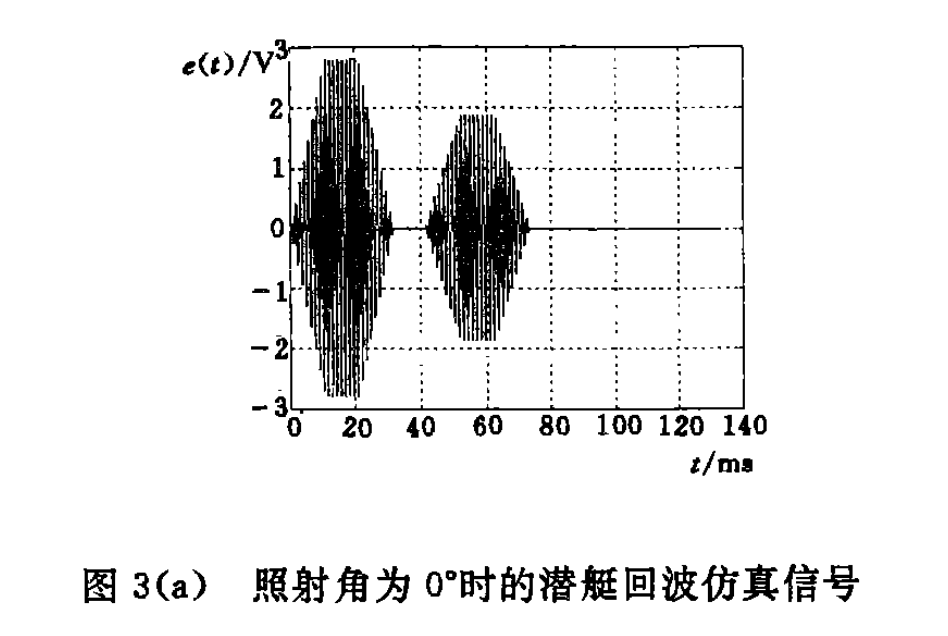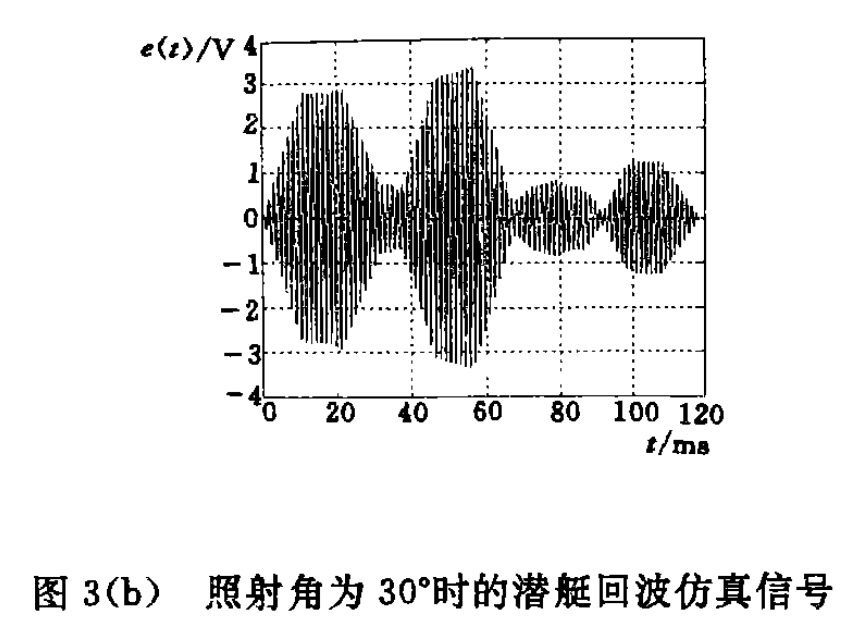

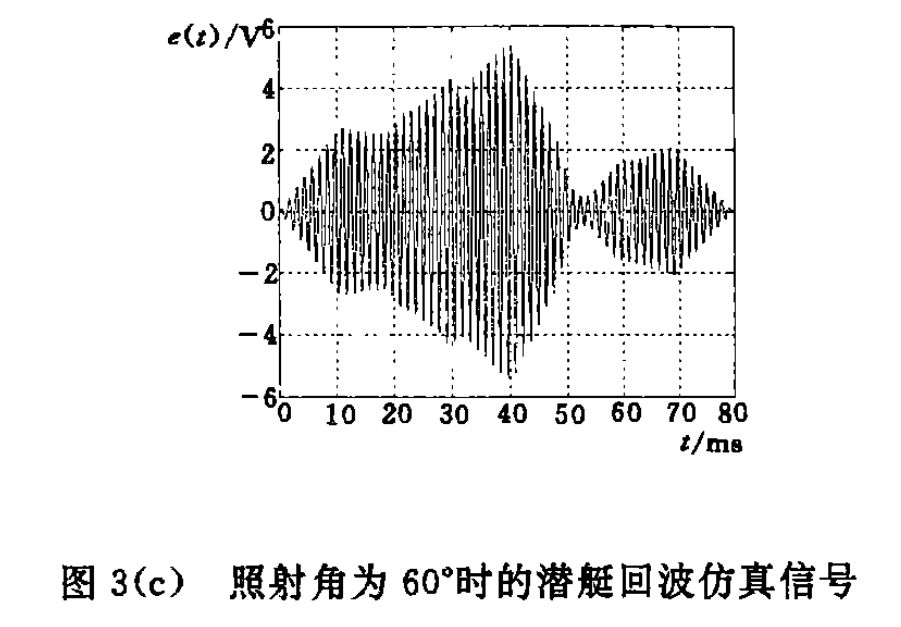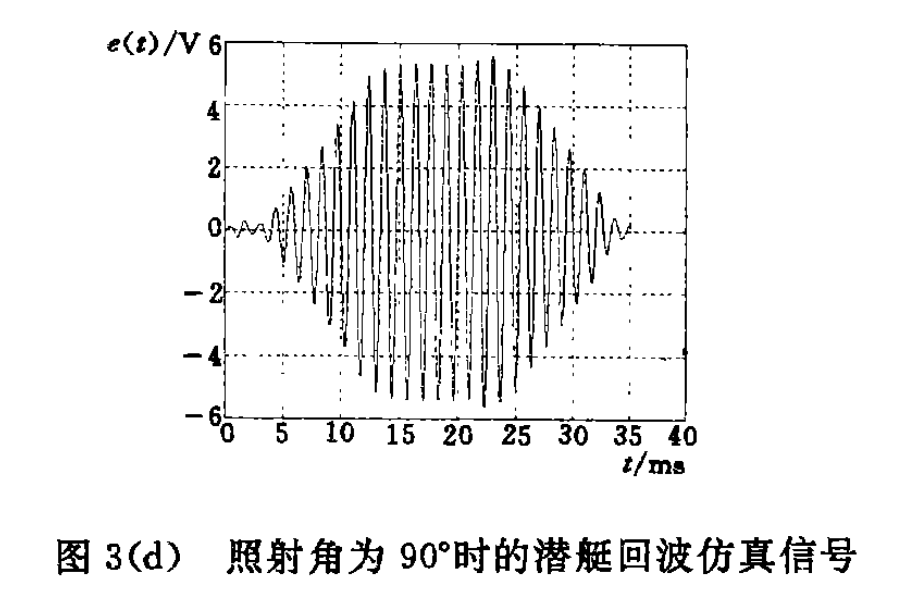

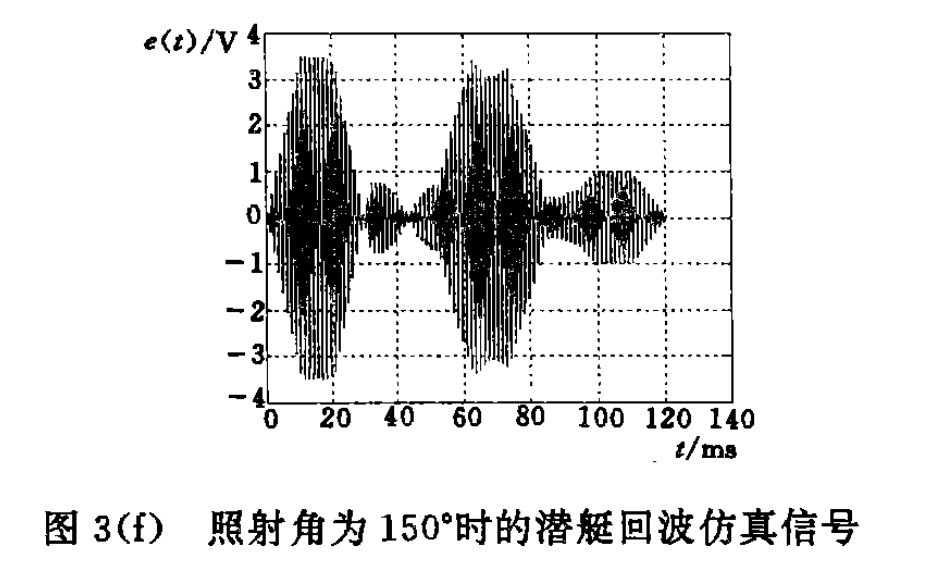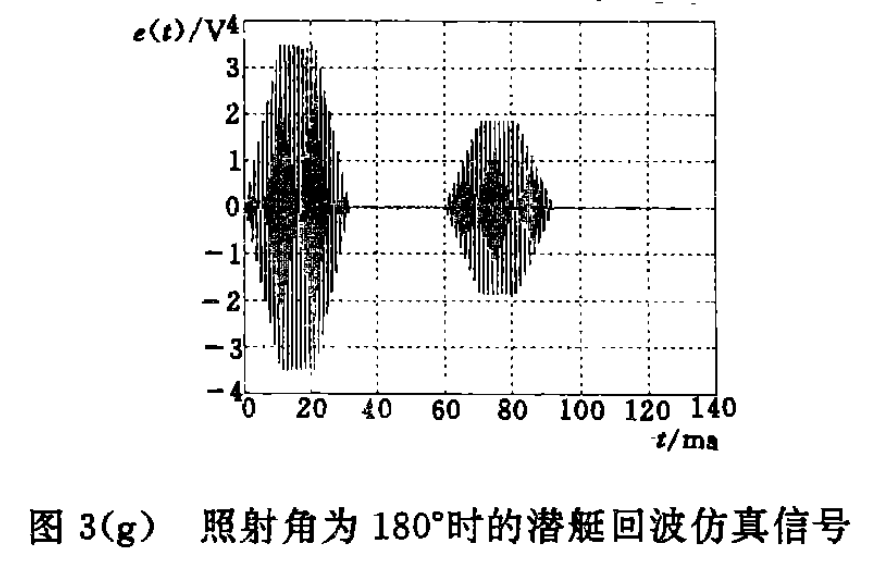

不一样的原因：跳变相位（不是pi？）

不符合0°~180°的规律

## 计算目标强度：

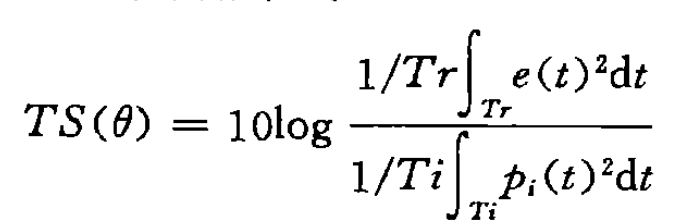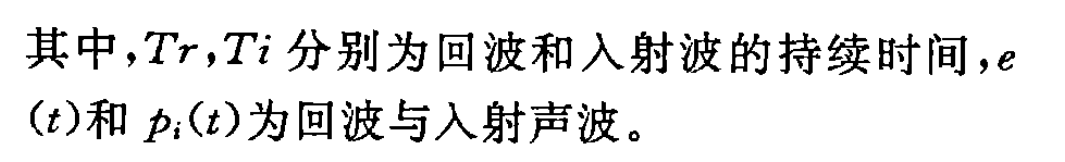

%根据回波的包络计算脉宽

figure
%回波包络
subplot(2,1,1)
plot(t, abs(echo));
xlabel('时间/s');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波包络', theta));
axis([0,10,-6,6]);grid on;
%入射波包络
subplot(2,1,2)
P = [P,zeros(1,length(t)-length(P))];
plot(t, abs(P));
xlabel('时间/s');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波包络', theta));
axis([0,5,-6,6]);grid on;

%计算回波脉宽
start_index_echo = find(abs(echo) > 0, 1, 'first');%应该设置一个阈值
end_index_echo = find(abs(echo) > 0, 1, 'last');
W_echo = (t(end_index_echo) - t(start_index_echo));
fprintf('回波脉宽为：%.10f s\n', W_echo);
%入射波为32ms
fprintf('入射波波脉宽为：%.3f s\n', width);
%分子项
TS_submarine = 10*log10(  ( sum(real(echo).^2)/W_echo ) /     (  sum(real(P).^2)/width  )     );
fprintf('入射信号为%d° 时目标强度为：%.3f dB\n', theta,TS_submarine);